% Columbia University EEME E6602 - Modern Control Theory, Final Project
% Author: Alex Wei yw4467

M = 50;     % cart mass, kg
m = 250;    % pendulum mass, kg
l = 1;      % distance to center of mass, m
g = 9.81;
A = [0, 1, 0, 0; (M + m) * g / (M * l), 0, 0, 0; 0, 0, 0, 1; -m * g / M, 0, 0, 0];
B = [0; -1 / (M * l); 0; 1 / M];
C = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0];
D = zeros(3, 1);

rank_O = rank(obsv(A, C))

rank_O = 4

rank_C = rank(ctrb(A, B))

rank_C = 4

rank_A = rank(A)

rank_A = 3

eig_OL = eig(A)     % check internal stability

eig_OL =          0
         0
    7.6720
   -7.6720


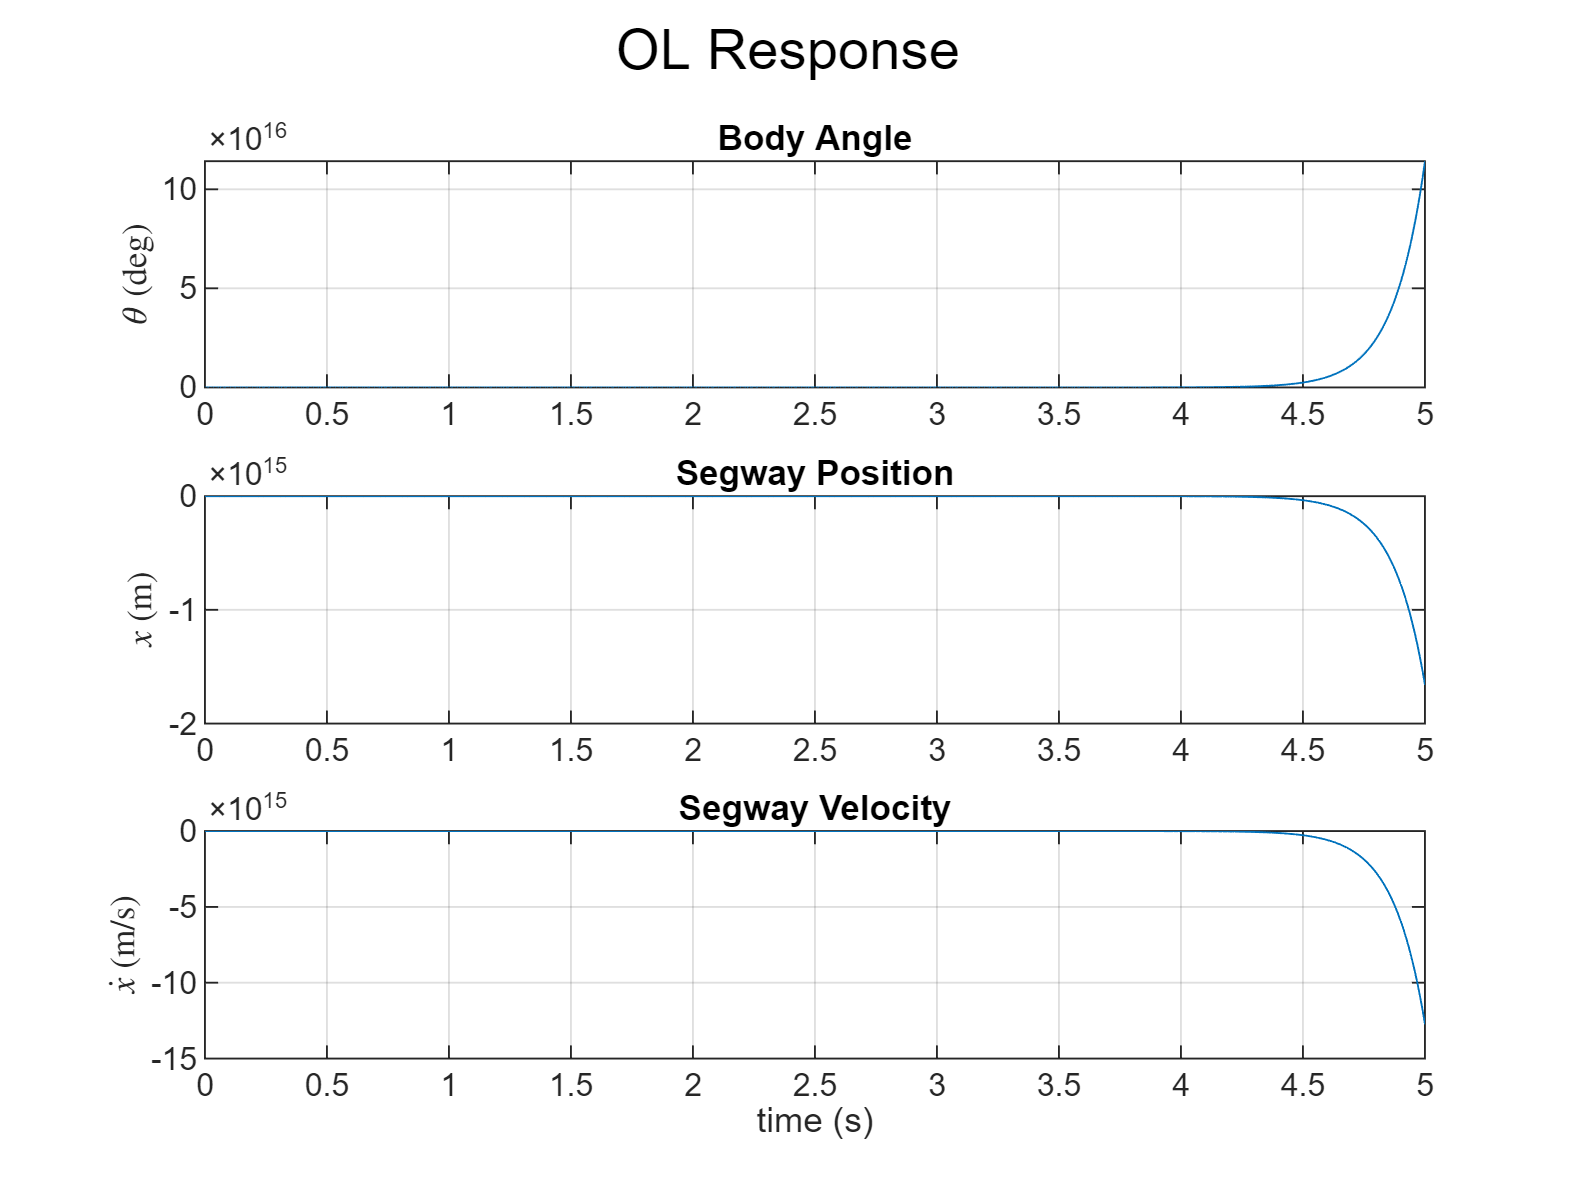


t = 0 : 0.01 : 5;
% OL sys
u = zeros(size(t));           % no input torque / force
x = [5 * pi / 180; 0; 0; 0];  % initial state: 5° tilt at rest
[y_ol, t_ol, x_ol] = lsim(ss(A, B, C, D), u, t, x);

figure;
subplot(3, 1, 1);
plot(t_ol, x_ol(:, 1) * 180 / pi);
title('Body Angle');
ylabel('$\theta$ (deg)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 2);
plot(t_ol, x_ol(:, 3));
title('Segway Position');
ylabel('$x$ (m)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 3);
plot(t_ol, x_ol(:, 4));
title('Segway Velocity');
ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('OL Response');


% CL
% LQR controller design (ideal state fb)
Q = diag([100, 1, 10, 1]);
R = 1;
[K_lqr, ~, ~] = lqr(A, B, Q, R)

K_lqr = 1.0e+03 *

   -6.0012   -0.8189   -0.0032   -0.0444



A1 = A - B * K_lqr;
eig_LQR = eig(A1)

eig_LQR =   -7.6721 + 0.0035i
  -7.6721 - 0.0035i
  -0.0726 + 0.0725i
  -0.0726 - 0.0725i


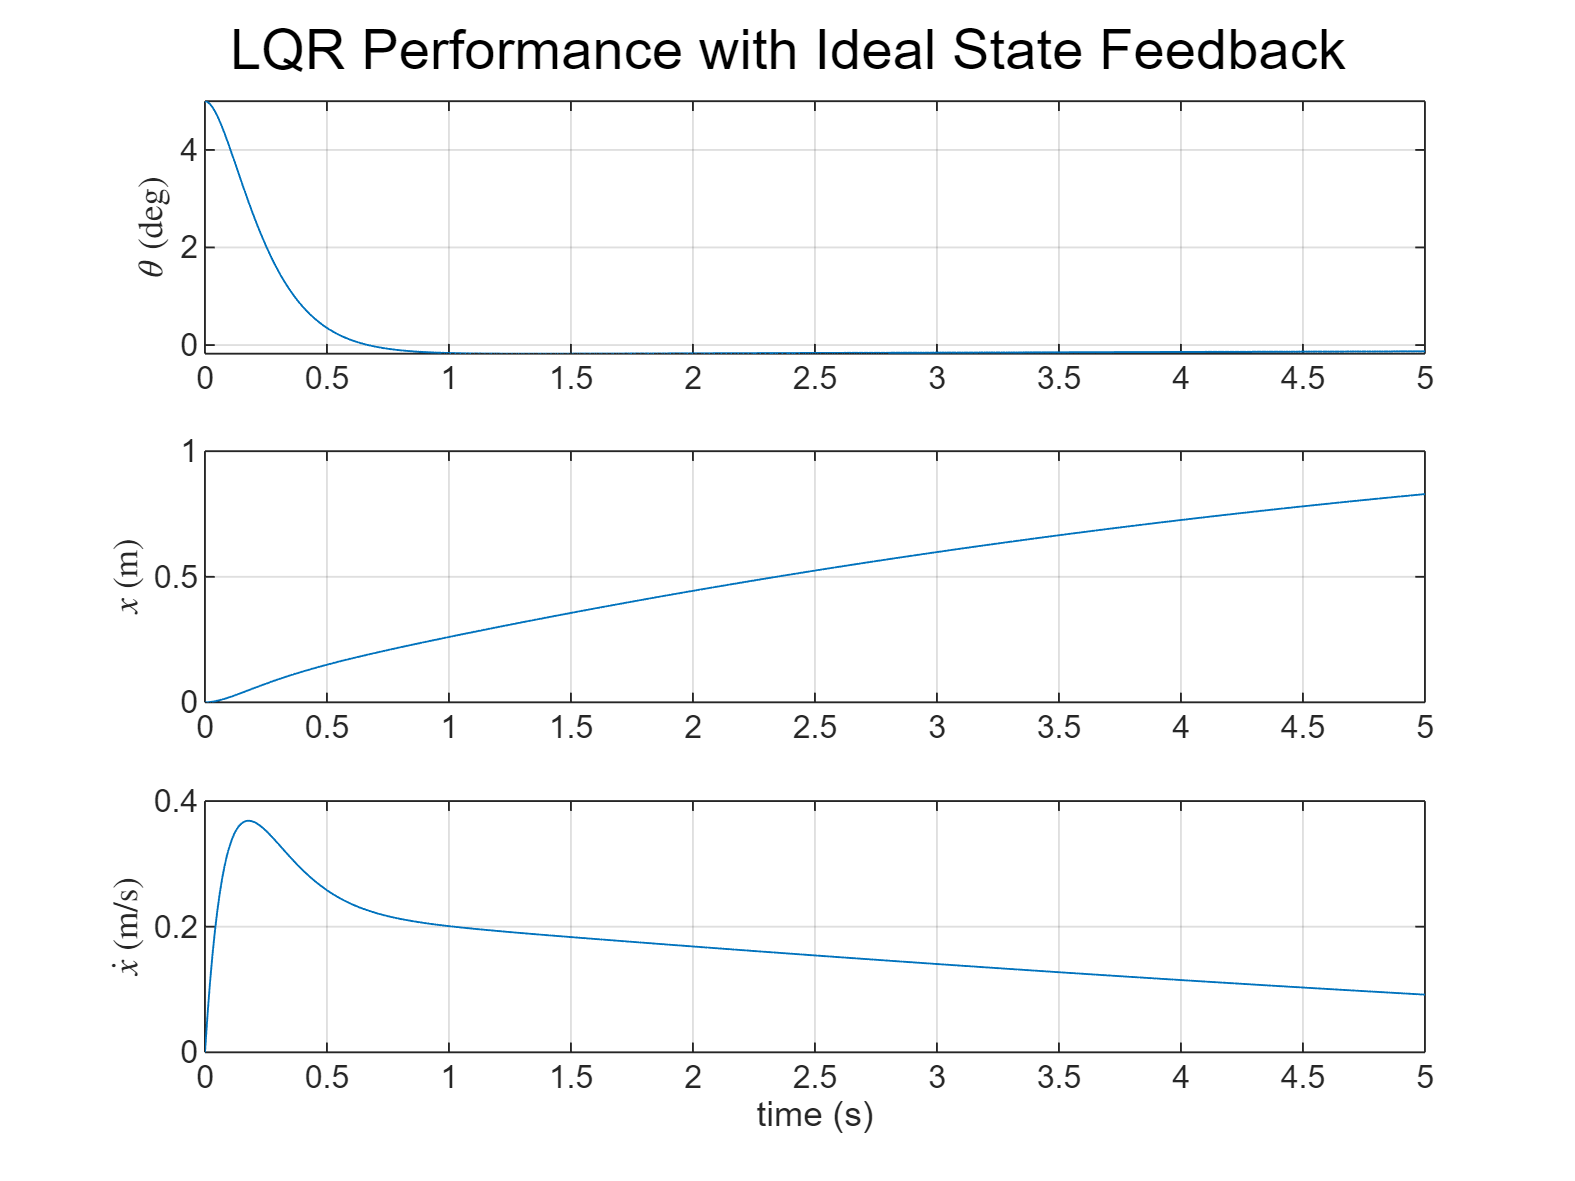

[~, t0, x0] = lsim(ss(A1, B, C, D), u, t, x);

figure;
subplot(3, 1, 1);
plot(t0, x0(:, 1) * 180 / pi);
ylabel('$\theta$ (deg)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 2);
plot(t0, x0(:, 3));
ylabel('$x$ (m)', 'Interpreter', 'latex');
grid on;
subplot(3, 1, 3);
plot(t0, x0(:, 4));
ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('LQR Performance with Ideal State Feedback');


% Luenberger Observer based LQR controller. ref: [1]
if rank(obsv(A, C)) == size(A, 1)
    L_obs = place(A', C', [-15; -16; -17; -18])' % chosen through t/e on LHP
end

L_obs =    17.0000    1.0000    0.0000
   58.8600   18.0000         0
    0.0000         0   31.0000
  -49.0500         0  240.0000



A0 = [A, -B * K_lqr; L_obs * C, A - L_obs * C - B * K_lqr];
B0 = [zeros(size(B)); zeros(size(B))]; % no external input
C0 = [C, zeros(size(C))]; % output y from plant states
D0 = zeros(size(C0, 1), size(B0, 2));
eig_LQR_obs = eig(A0)

eig_LQR_obs =   -0.0726 + 0.0725i
  -0.0726 - 0.0725i
  -7.6721 + 0.0035i
  -7.6721 - 0.0035i
 -17.0000 + 0.0000i
 -15.0000 + 0.0000i
 -16.0000 + 0.0000i
 -18.0000 + 0.0000i


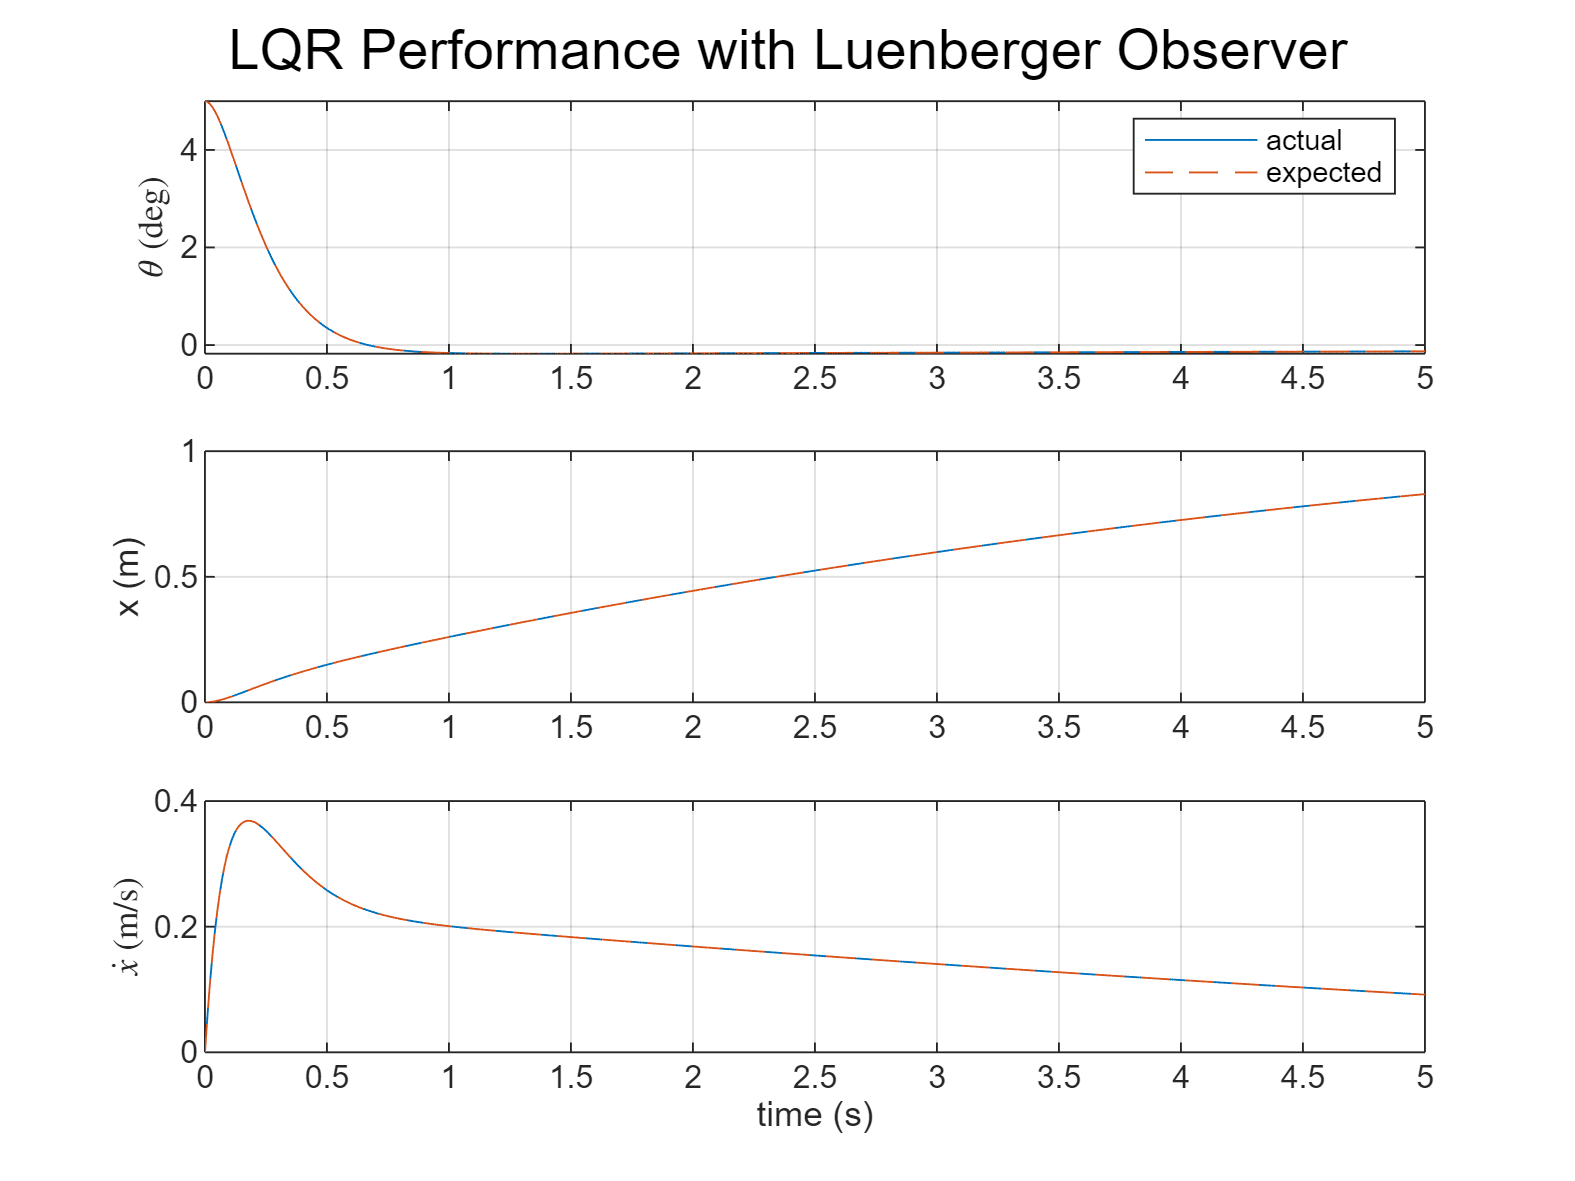


[~, t1, x1] = lsim(ss(A0, B0, C0, D0), u, t, [x; x]);
x1_plt = x1(:, 1:size(A, 1));
x1_hat = x1(:, size(A, 1) + 1:end);

figure;
subplot(3, 1, 1);
plot(t1, x1_plt(:, 1) * 180 / pi);
hold on;
plot(t1, x1_hat(:, 1) * 180 / pi, '--');
ylabel('$\theta$ (deg)', 'Interpreter', 'latex');
grid on;
legend('actual', 'expected');
subplot(3, 1, 2);
plot(t1, x1_plt(:, 3));
hold on;
plot(t1, x1_hat(:, 3), '--');
ylabel('x (m)');
grid on;
subplot(3, 1, 3);
plot(t1, x1_plt(:, 4));
hold on;
plot(t1, x1_hat(:, 4), '--');
ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('LQR Performance with Luenberger Observer');

H-infinity controller synthesized with gamma = 0.37092


H-infinity controller K:


                A: [4×4 double]
                B: [4×3 double]
                C: [6.1637e+03 869.2660 10.0504 80.8603]
                D: [0 0 0]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {4×1 cell}
        StatePath: {4×1 cell}
        StateUnit: {4×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: 0
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



eig_hinf =  -11.7327 + 8.0992i
 -11.7327 - 8.0992i
  -8.3598 + 0.0000i
  -7.7773 + 0.0000i
  -1.7350 + 1.1039i
  -1.7350 - 1.1039i
  -0.1253 + 0.1283i
  -0.1253 - 0.1283i


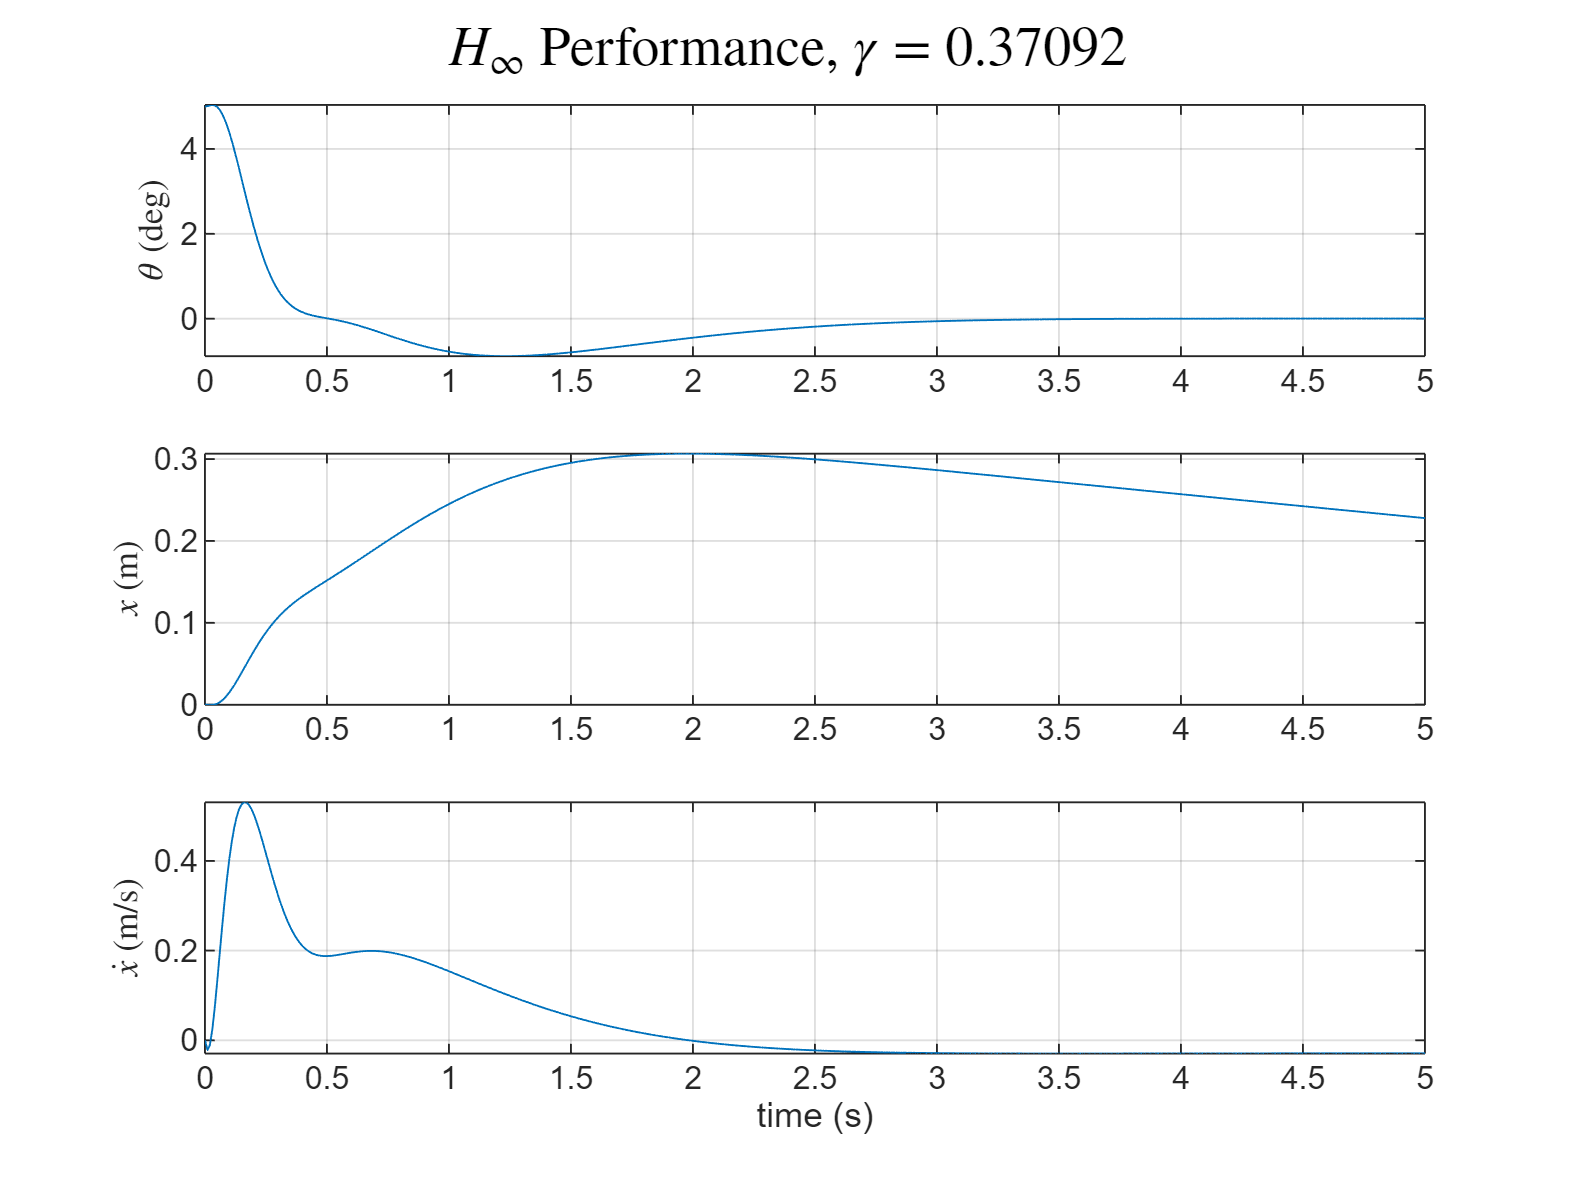


% H-infinity output fb controller design. ref: [2]
B1 = B;
B2 = B;
W_theta = 20; % weight on pendulum angle
W_x_pos = 1;  % weight on cart position
W_u = 0.1;    % weight on control input
C1 = [W_theta * C(1, :); W_x_pos * C(3, :); zeros(1, size(A, 2))];
D11 = zeros(size(C1, 1), size(B1, 2));
D12 = [0; 0; W_u];
C2 = C;
D21 = zeros(size(C2, 1), size(B1, 2));
D22 = D;

[K, ~, GAM, ~] = hinfsyn(ss(A, [B1, B2], [C1; C2], [D11, D12; D21, D22]), 3, 1, 1, hinfsynOptions('RelTol', 1e-4));
if ~isempty(K) && GAM > 0
    disp(['H-infinity controller synthesized with gamma = ', num2str(GAM)]);
    disp('H-infinity controller K:');
    disp(get(K));

    [Ak, Bk, Ck, Dk] = ssdata(K);
    Ah = [A + B * Dk * C, B * Ck; Bk * C, Ak];
    Bh = zeros(size(Ah, 1), 1);
    Ch = [C, zeros(size(C, 1), size(Ck, 2))];
    Dh = zeros(size(Ch, 1), size(Bh, 2)); 
    eig_hinf = eig(Ah)
    
    [~, t2, x2] = lsim(ss(Ah, Bh, Ch, Dh), u, t, [x; zeros(size(Ak, 1), 1)]);
    x2_plt = x2(:, 1 : size(A, 1));
    
    figure;
    subplot(3, 1, 1);
    plot(t2, x2_plt(:, 1) * 180 / pi);
    ylabel('$\theta$ (deg)', 'Interpreter', 'latex');
    grid on;
    subplot(3, 1, 2);
    plot(t2, x2_plt(:, 3));
    ylabel('$x$ (m)', 'Interpreter', 'latex');
    grid on;
    subplot(3, 1, 3);
    plot(t2, x2_plt(:, 4));
    ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex');
    xlabel('time (s)');
    grid on;
    sgtitle(['$H_{\infty}$ Performance, $\gamma$ = ', num2str(GAM)], 'Interpreter', 'latex');
end

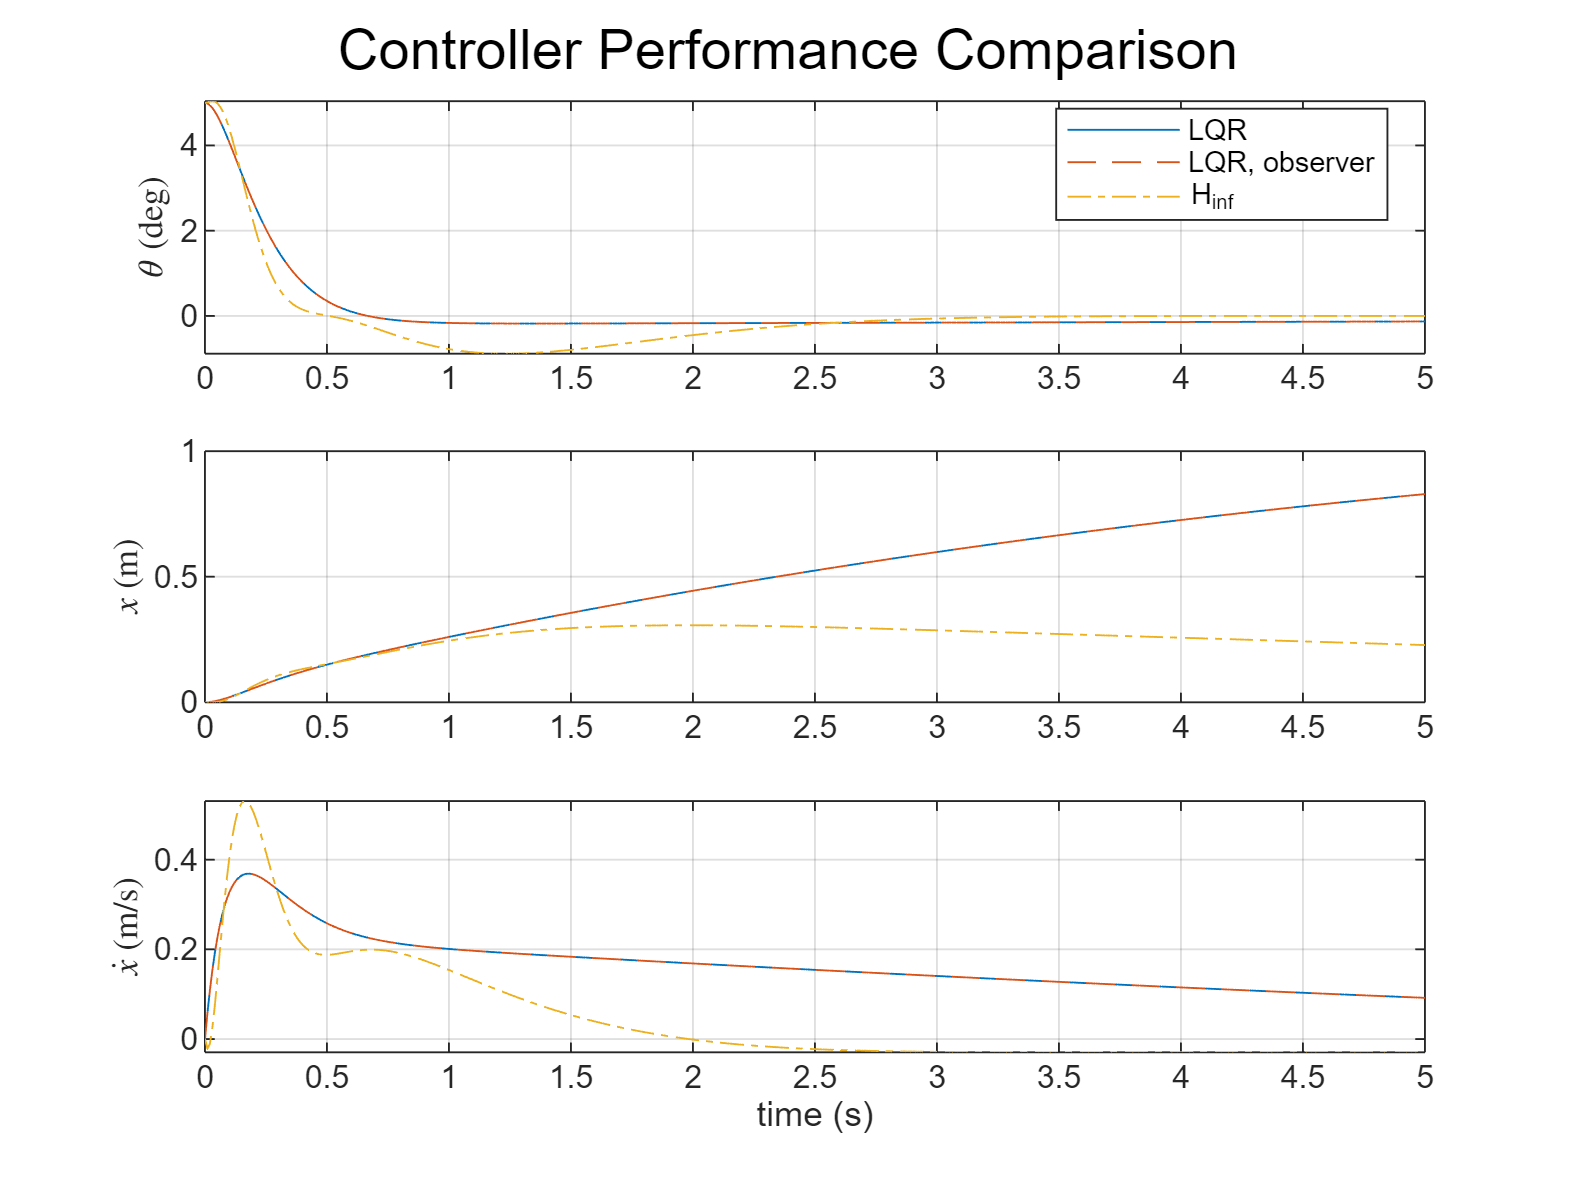


% comprehensive comparison
figure;
subplot(3, 1, 1);
plot(t0, x0(:, 1) * 180 / pi, '-');
hold on;
plot(t1, x1_plt(:, 1) * 180 / pi, '--');
plot(t2, x2_plt(:, 1) * 180 / pi, '-.');
legend('LQR', 'LQR, observer', 'H_{inf}', 'Location', 'best');
ylabel('$\theta$ (deg)', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 2);
plot(t0, x0(:, 3), '-');
hold on;
plot(t1, x1_plt(:, 3), '--');
plot(t2, x2_plt(:, 3), '-.');
ylabel('$x$ (m)', 'Interpreter', 'latex');
grid on;

subplot(3, 1, 3);
plot(t0, x0(:, 4), '-');
hold on;
plot(t1, x1_plt(:, 4), '--');
plot(t2, x2_plt(:, 4), '-.');
ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex');
xlabel('time (s)');
grid on;
sgtitle('Controller Performance Comparison');

### References

[1] *Implementation of State Observer in spring Mass damper*. (2023, May 1). Implementation of State Observer in Spring Mass Damper - File Exchange - MATLAB CentralFile Exchange - MATLAB Central. https://ww2.mathworks.cn/matlabcentral/fileexchange/128864-implementation-of-state-observer-in-spring-mass-damper

[2] *F14 H-Infinity Loop-Shaping Design example*. (2022, March 4). F14 H-Infinity Loop-Shaping Design Example - File Exchange - MATLAB CentralFile Exchange - MATLAB Central. https://ww2.mathworks.cn/matlabcentral/fileexchange/50216-f14-h-infinity-loop-shaping-design-example